% Function for predicting the properties of humid air (density, dynamic
% viscosity, thermal conductivity, and specific heat capacity) for a given
% temperature (in Celsius) and relative humidity (as a fraction 0-1).

% Limitation: These correlations are valid for temperature above zero
% Celsius
function [rho_air,mu_m,k_m,cp_m]=MoistAirProperties(t,RH)
global p  T pd pv ps
    
% T is the temperature in Kelvin, while t is in Celsius
    T=t+273.15;

Defining constants

    
    p=101325; % Standard Atmospheric Pressure at Sea Level (Pa)
    
    % Molar mass of dry air and water, respectively
    M=[28.9635 18.01528]; % g/mol
    
    % Specific gas constants for dry air and water vapor, respectively
    Rd=287.058; % J/(kg·K) 
    Rv=461.495; % J/(kg·K)
    

Partial Pressure Calculation

    
    % Compute the partial pressures of dry air and water vapor
    [pd,pv] = partialpressures(t,RH);

Moist Air Density Calculation

    % Density of moist air
    rho_air=(pd / (Rd * T)) + (pv / (Rv * T));
    

Molar Fraction Calculation

    % Compute the molar fractions
    X=[pd/p pv/p];
    

 Molar mass of mixture

    
     M_m=M(1)*(1-X(2))+M(2)*X(2);
    

## Moist Air Viscosity Calculation

Using Tsiligiris' formulas for vapor and dry air viscosities

   % Compute the dynamic viscosities of dry air and water vapor using
   % Tsiligiris formula
   tsi_mu = tsi_dynamicvisc(t);
    
   % Compute the interaction parameter phi using Tsi's mu
   

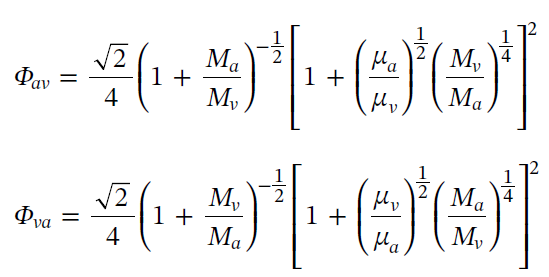

    phi=zeros([2 2]);
    phi(1,1)=1;
    phi(2,2)=1;
    phi(1,2)=sqrt(2)/4*(1+M(1)/M(2))^(-1/2)*(1+sqrt(tsi_mu(1)/tsi_mu(2))*(M(2)/M(1))^(1/4))^2;
    phi(2,1)=sqrt(2)/4*(1+M(2)/M(1))^(-1/2)*(1+sqrt(tsi_mu(2)/tsi_mu(1))*(M(1)/M(2))^(1/4))^2;

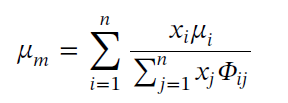

   sumi=0;
    sumj=0;
    
    for i=1:2 
        for j=1:2
          sumj=sumj+X(j)*phi(i,j);
        end
       sumi=sumi+X(i)*tsi_mu(i)/sumj; 
       sumj=0;
    end
    mu_m=sumi;
    
    

## Moist Air Conductivity Calculation

    
k=thermalconduc(t);
A=(X(1)*k(1))/(X(1)+X(2)*phi(1,2));
B=(X(2)*k(2))/(X(2)+X(1)*phi(2,1));
k_m=A+B;


## Moist Air Specific Heat Capacity Calculation

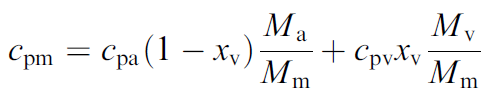

cp=spcfcheat(t); % kJ/kg.K

cp_m=(cp(1)*(1-X(2))*M(1)/M_m+cp(2)*X(2)*M(2)/M_m)*1000; % convert from kJ to J

end

## Local Functions

function [pd,pv] = partialpressures(t,RH)

global p pd pv ps

    if t>0 % water
    ps=exp(34.494-4924.99/(t+237.1))/(t+105)^1.57;
    f=1.00071*exp(0.000000045*p);
    
    else %ice
    ps=exp(43.494-6545.8/(t+278))/(t+868)^2;
    f=0.99882*exp(0.00000008*p);
    end

pv = ps*f*RH;
pd = p - pv;
end


Tsilingiris's dynamic viscosity

function tsi_mu = tsi_dynamicvisc(t)
global T

% Dynamic viscosity of dry air as a function of temperature 

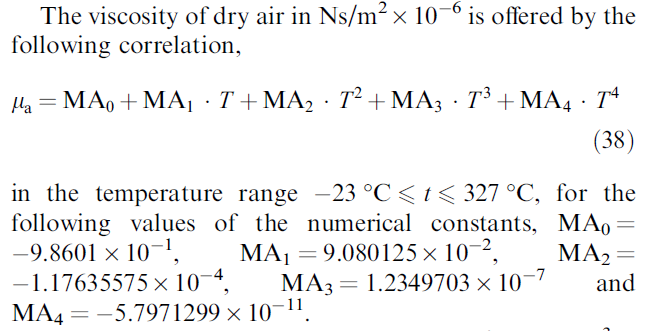


MA=[-9.8601e-1 9.080125e-2 -1.17635575e-4 1.2349703e-7 -5.7971299e-11];

tsi_mu(1) = (MA(1)+MA(2)*T+MA(3)*T^2+MA(4)*T^3+MA(5)*T^4)*10^-6;

% Dynamic viscosity of vapor as a function of temperature 

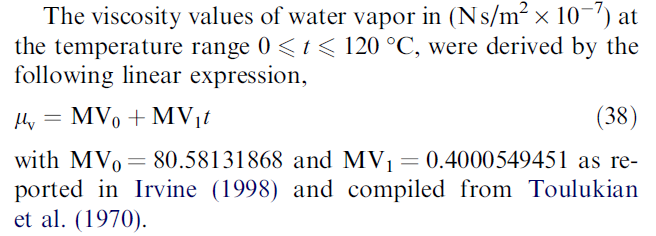

tsi_mu(2)=(8.058131868e01+(4.000549451e-01)*t)*10^-7;
 
end

Tsilingiris's Thermal conductivity

function k=thermalconduc(t)
global T

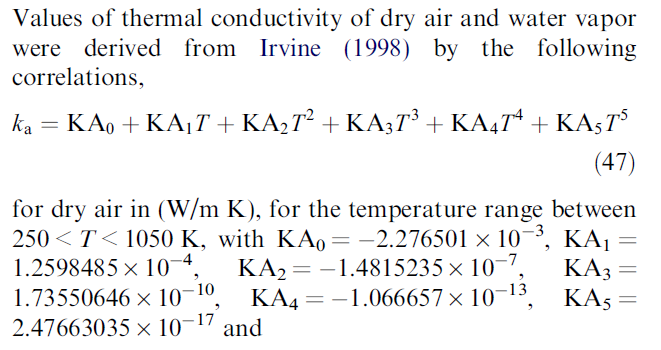

% Thermal conductivity of dry air

KA=[-2.276501e-3 1.2598485e-4 -1.4815235e-7 1.73550646e-10 -1.066657e-13 2.47663035e-17];
k(1)=(KA(1)+KA(2)*T+KA(3)*T^2+KA(4)*T^3+KA(5)*T^4+KA(6)*T^5);

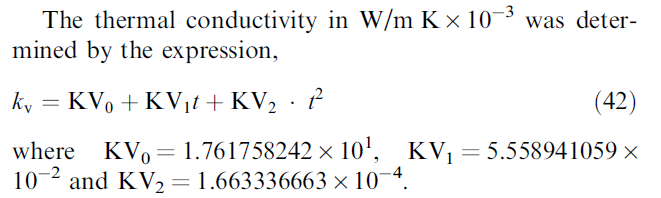

% Thermal conductivity of saturated water
KV=[1.761758242e01 5.558941059e-2 1.663336663e-4];
k(2)=(KV(1)+KV(2)*t+KV(3)*t^2)*10^-3;
end

Tsilingiris's Specific Heat Capacity

function cp=spcfcheat(t)
global T

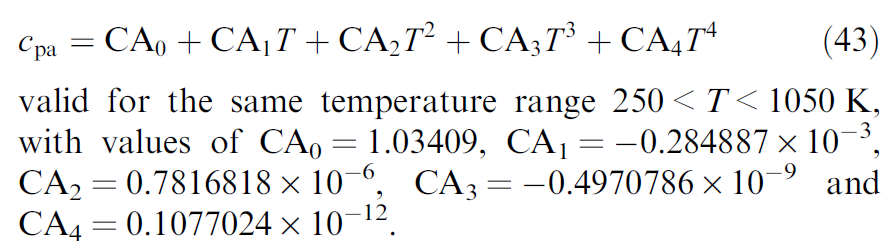

% Specific heat capacity of dry air
CA=[1.03409 -0.284887e-03 0.7816818e-06 -0.4970786e-09 0.1077024e-12];
cp(1)=CA(1)+CA(2)*T+CA(3)*T^2+CA(4)*T^3+CA(5)*T^4;


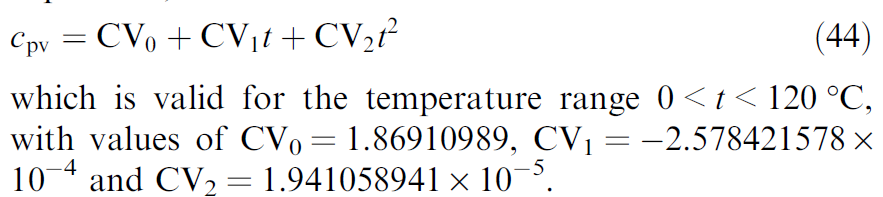

CV=[1.86910989 -2.578421578e-04 1.941058941e-05];
cp(2)=CV(1)+CV(2)*t+CV(3)*t^2;
end